# Linear Control Design 2 - Fall 2022 - Exam Part I

## Introduction

The Part I of the Exam in Linear Control Design 2 (E22) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**The scoring of each problem is clearly stated.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E22'

Exam = 'LCD2 E22'

Student_Name = 'Student Name'

Student_Name = 'Student Name'

Student_Number = 'Student Number'

Student_Number = 'Student Number'

## Optimal output feedback control of a balance system

A balance system is a mechanical system in which the center of mass is balanced above a pivot point. A popular example of a balance system is the Segway Personal Transporter (shown in the figure below) where a motorized platform is used to stabilize the person standing on top of it. Balance systems are a generalization of a mass-spring-damper system to multi-degree-of-freedom, and the inverted pendulum on a cart (also shown in the figure below) is a good mechanical approximation of such systems.

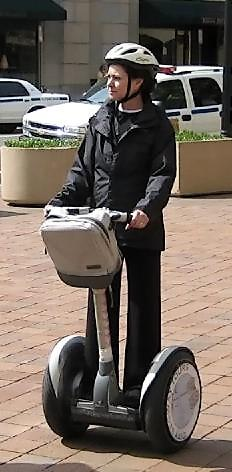            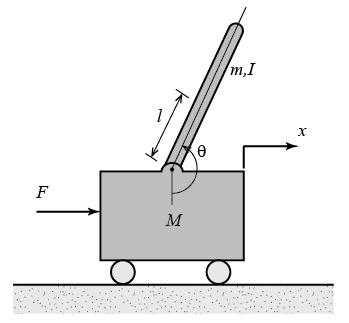

For this system the control input is the force $F$ that moves the cart in the longitudinal direction, and the measured output is the longitudinal position $x$ of the cart. The control objective is to keep the pendulum in its uprigth position ($\theta = \pi$rad) while moving the cart along the longitudinal direction. This is equivalent to the Segway Personal Transporter keeping its upright position while the rider leans forward to move along the ground. 

### Nonlinear model of the inverted pendulum on a cart

The nonlinear model describing the dynamical variations of the angular position of the pendulum $\theta$ and the linear position of the cart $x$ is described by the following nonlinear coupled second order differential equations

$(I + ml^2)\ddot{\theta} + c\dot{\theta} +mgl\sin\theta = -ml\ddot{x}\cos\theta  \\
(M+m)\ddot{x}+b\dot{x}+ml\ddot{\theta}\cos \theta-ml\dot{\theta}^2 \sin \theta = F \\
y = x$       (1)

where

- $M$is the mass of the cart

- $m$ is the mass of the pendulum

- $I$ is the inertia of the pendulum

- $b$ is the viscous friction coefficient of the cart

- $c$ is the viscous friction coefficient of the pendulum

- $l$ is the lenght of the pendulum

- $g$ is the gravitational constant 

The nonlinear model in Eq. (1) is implemented in the Simulink file InvertedPendulum_SimulinkYYYYC, where YYYYC refers to the Simulink version (2021b, 2021a, 2020b, 2020a, 2019b, 2019a, 2018b, 2018a, 2017b, 2017a). The numerical values for the model parameters are provided right below.

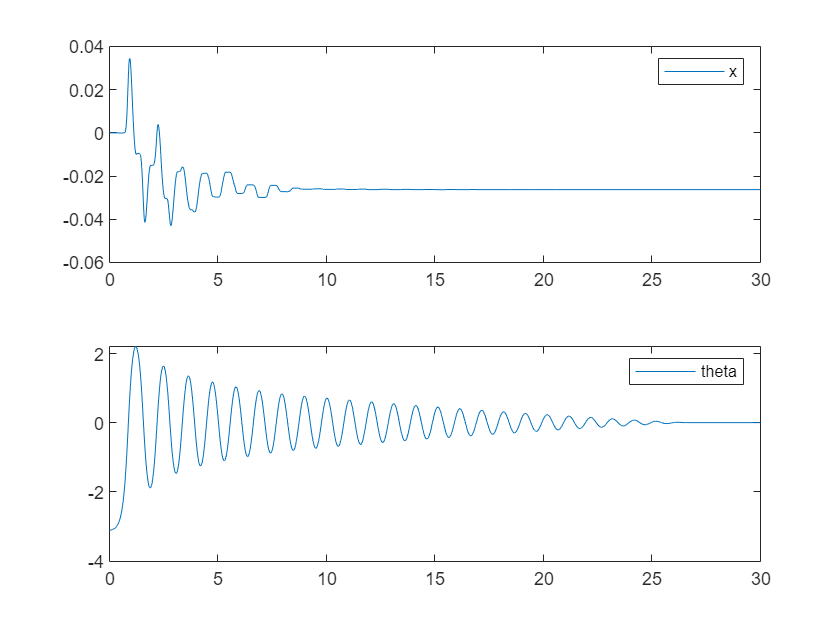

clear all
clc
load zero_input.mat
x_meas = x;
theta_meas = deg2rad(theta);
%x_meas = x_meas(fix(1.5/0.001):end);
%theta_meas = theta_meas(fix(1.5/0.001):end);
%t = t(1:length(theta_meas));
x_exp = [t', x_meas'];
theta_exp = [t', theta_meas'];
figure;
subplot(2,1,1);
plot(t, x_meas);
legend('x');
subplot(2,1,2);
plot(t, theta_meas);
legend('theta');

% DRIVE TRAIN ---------------------------------------------------------------

% 1) Large pulleys
r = 25e-3/2; % large pulley drive radius
mlt = 14.3e-3; % total mass of pulley
r1 = r;
r2 = 18e-3/2;
l1 = 9e-3;
l2 = 6e-3;
v1 = pi * r1^2 * l1 - pi * r^2 * l1;
v2 = pi * r2^2 * l2 - pi * r^2 * l2;
vlt = v1 + v2;
Jlp = 1/2*mlt*v1/vlt*(r1^2 + r^2) + 1/2*mlt*v2/vlt*(r2^2 + r^2); % moi of large pulley

% 2) Small pulley
rs = 12e-3/2; % small pulley drive radius
mst = 4.6e-3; % total mass of small pulley
r1 = r;
r2 = 16e-3/2;
l1 = 7.4e-3;
l2 = 7.6e-3;
v1 = pi * r1^2 * l1 - pi * rs^2 * l1;
v2 = pi * r2^2 * l2 - pi * rs^2 * l2;
vst = v1 + v2;
Jsp = 1/2*mst*v1/vst*(r1^2 + rs^2) + 1/2*mst*v2/vst*(r2^2 + rs^2); % moi of small pulley


% 3) Large belt
philb = 0.2e-3/23.3e-3; % belt mass pr. meter length
llb = 2*34.5e-2 + 2 * 28.5e-2 + 2 * 2*r*pi; % belt length
mlb = philb * llb; % belt mass
Jlb = mlb * r^2; % moi of large belt

% 4) Small belt
msb = 2e-3; 
Jsb = msb * rs^2;

% 5) Coupling rods
mr = 40.8e-3; % mass of rod
rr = 4e-3; % radius of rod
Jr = 1/2 * mr * rr^2; % moi of rod

% 6) Total drive
Jd = 2 * Jlp + 2 * Jsp + Jlb + Jsb; % total moi for drive train components

% MOTOR --------------------------------------------------------------------
R = 3.3; % armature resistance [Ω]
L = 1.25e-3; % armature inductance [H]
kt = 0.0285; % torque constant [Nm/A]
ke = 0.0285;% electromotive force constant [Vs/rad]
J = 1.12e-6; % rotor inertia [kg m^2]
B = 6.5559e-5; % viscous motor friction [Ns\m]

% PENDULUM AND CART
M =632; % mass of cart [kg]
m = 0.181; % mass of pendulum [kg]
I = 1/12*m*(2*L)^2; % moi of pendulum [kg m^2]
g = 9.8; % gravity constant [m/s^2]
l = 0.365/2; % lenght of pendulum rod [m]
c = 0.01; % friction coefficient pendulum [kg m^2/s]                ESTIMATE
mu_k = 0.2; % kinetic friction coefficient cart                     ESTIMATE
mu_s = 0.2; % static friction coefficient cart                      ESTIMATE
FN = (m + M)*g; % normal force on cart [N]
mu_v = 0.3; % viscous friction coefficient cart                     ESTIMATE
a_st = 1;   % can't remember the name                               ESTIMATE



M =632; % mass of trolley [kg]
m = 0.181; % mass of pendulum bob [kg]
b = 0;%0.1; % friction coefficient trolley [k 0.g/s]
c = 0;%0.01; % friction coefficient pendulum [kg m^2/s]
bc = b;
bp = c;
g = 9.8; % gravity constant [m/s^2]
l = 0.365/2; % lenght of pendulum rod [m]
L = 0.365/2;
I = 1/12*m*(2*L)^2; % inertia of pendulum [kg*m^2]
Jp = I;

R = 3.3; % armature resistance [Ω]
L = 1.25e-3; % armature inductance [H]
Kt = 0.0285; % torque constant [Nm/A]
Ke = 0.0285;% electromotive force constant [Vs/rad]
J = 1.12e-6; % rotor inertia [kg m^2]
B = 6.5559e-5; % viscous motor friction [Ns\m]


% Rm = 3.3;
% Lm = 1.25e-3;
% kt = 0.0491;
% ke = kt;
% Jm = 1.55e-5;
% bm = 9.25e-6;
r = 25e-3/2;
theta_dot0 = 0; % pendulum angular velocity [rad/s]
theta0 = theta_meas(1); % pendulum angular position [rad]
dtheta0 = 0;
dx0 = 0;
x_dot0 = 0; % trolley linear velocity [m/s]
x0 = 0; % trolley linear position [m]
F0 = 0; % linear force applied to the trolley [N]
SIM_TIME = 30; % simulation time (can be changed as needed - if simulated for longer time, the pendulum returns to the downward position)
STEP_SIZE = 0.001; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'final/pend_m_motor';
time = (0:STEP_SIZE:SIM_TIME)';
F_ctrl = F0*ones(length(time),1);

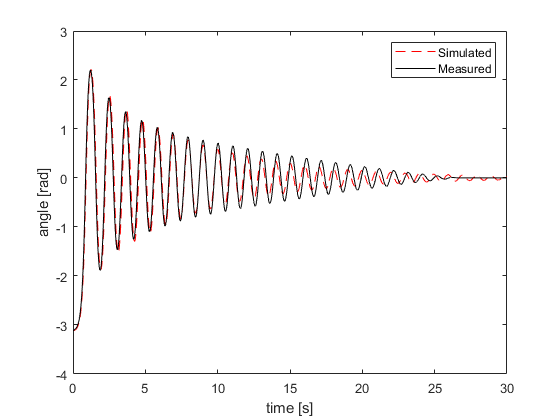

sim(SIMULINK_FILENAME,SIM_TIME,[],[time F_ctrl])

% Plot the temporal behaviour of the quantities of interest (RG)
theta_dot = rad2deg(logsout.getElement('theta_dot').Values.Data);
theta = deg2rad(wrapTo180(rad2deg(logsout.getElement('theta').Values.Data))); % the pendulum angular position is wrapped between -180 and 180 degress
x_dot = logsout.getElement('x_dot').Values.Data;
x = logsout.getElement('x').Values.Data;

figure;
plot(time, theta, '--r', t, theta_meas, 'k')
legend('Simulated', 'Measured')
ylabel('angle [rad]');
xlabel('time [s]');

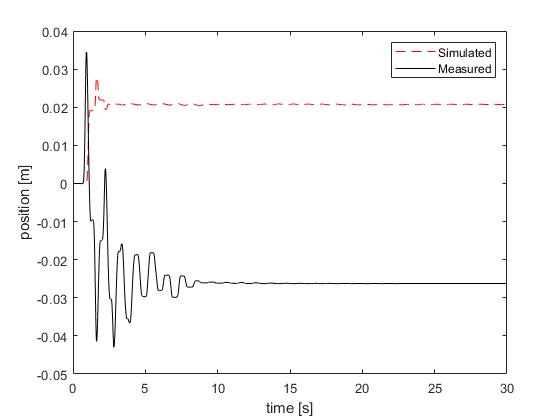


figure;
plot(time, x, '--r', t, x_meas, 'k')
ylabel('position [m]')
xlabel('time [s]')
legend('Simulated', 'Measured')

SIMULINK_FILENAME = 'InvertedPendulum_Simulink2017a';
[A, B, C, D] = linmod(SIMULINK_FILENAME, [theta_dot0;theta0;x_dot0;x0], 0, 0)

A =    -0.3450   40.2662   -0.0000         0
    1.0000         0         0         0
   -0.0000    0.0021   -0.0000         0
         0         0    1.0000         0


B = 1.0e-06 *

    0.7016
         0
    0.1708
         0


C =      0     0     0     1
     0     1     0     0


D =      0
     0


**Problem 2 [2 points]** Evaluate the internal and the external stability of system.

[v, lbds] = eig(A);
disp('Eigenvectors for linearized system')

Eigenvectors for linearized system


v

v =          0   -0.9884   -0.9871    0.0000
         0    0.1516   -0.1598   -0.0000
         0   -0.0001   -0.0001   -0.0000
    1.0000    0.0000   -0.0000    1.0000


disp('Eigenvalues for linearized system')

Eigenvalues for linearized system


lbds = diag(lbds)

lbds =          0
   -6.5204
    6.1754
   -0.0000


% %[num, den] = ss2tf(A,B,C,D,1);
% G_ol = tf(num, den);
% disp('Poles for open loop system')
% pole(minreal(G_ol))
% disp('The system is internally unstable')
% disp('The system is externally unstable')

**Problem 3 [2 points]** Compute the step response of the system, and discuss the behaviour of the system state and output in the light of the stability analysis.

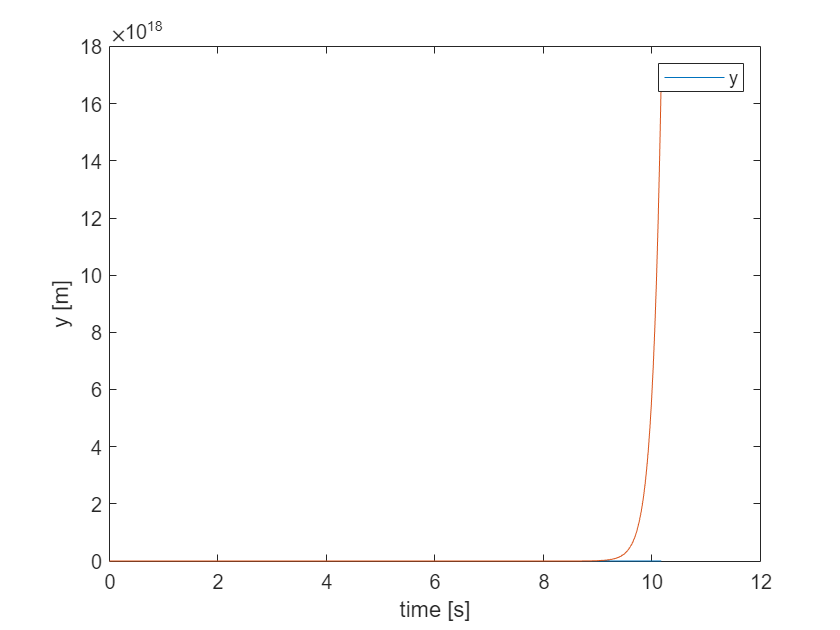

ss_ol_ct = ss(A,B,C,D);
[y_ct,t_ct, x_ct] = step(ss_ol_ct);
figure;
plot(t_ct, y_ct);
legend('y');
xlabel('time [s]');
ylabel('y [m]');

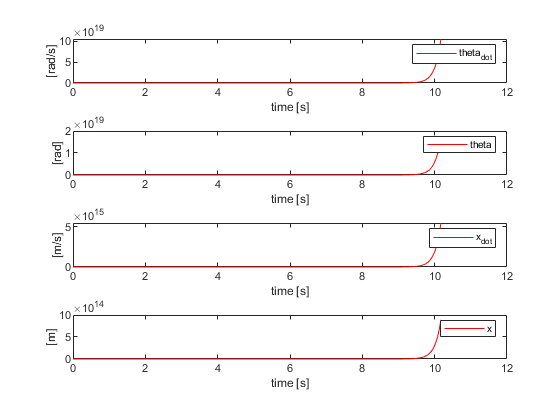

figure;
subplot(4,1,1);
plot(t_ct, x_ct(:,1),'r');
legend('theta_{dot}');
xlabel('time [s]');
ylabel('[rad/s]')
subplot(4,1,2);
plot(t_ct, x_ct(:,2),'r');
legend('theta');
xlabel('time [s]');
ylabel('[rad]')
subplot(4,1,3);
plot(t_ct, x_ct(:,3),'r');
legend('x_{dot}');
xlabel('time [s]');
ylabel('[m/s]')
subplot(4,1,4);
plot(t_ct, x_ct(:,4),'r');
legend('x');
xlabel('time [s]');
ylabel('[m]')

Here we see everything going towards infinity, which makes sense since the system was determined before to be internally unstable. We also see the output (cart position x) going towards infinity, this matches what was found in the previous exercise as the system was deemed externally unstable.

### Control system design for balance system

The main control objective is to maintain the pendulum in its upright position while the cart changes its position along the longitudinal direction, e.g. following a trajectory $x_{ref}(t)$. 

Closed-loop system requirements

The following closed-loop requirements should be fulfilled when the position of the cart changes of 1m

- The 1% settling time for $x$ is between 25 and 35 seconds;

- The pendulum angular position $\theta$ does not deviate more than $\pi/48 \, \mathrm{rad}$ ($\approx 4 \, \mathrm{deg}$) from the upright position;

- The steady state error is less than 3% for $x$

- The applied control force $F$ is within $\pm10\,\mathrm{N}$

- The pendulum angular position is kept at $\theta_{ref} = \pi \, \mathrm{rad}$.

**Problem 4 [6 points]** Under the assumption that the state is fully accessible design a discrete time optimal controller that meets the aforementioned requirements.

First i discretize the system

Ts = 0.02

Ts =    0.020000000000000


sys_ol_dt = c2d(ss_ol_ct,Ts);
F = sys_ol_dt.A;
G = sys_ol_dt.B;
Mr = ctrb(F,G);
if rank(Mr) == size(F,1)
    disp('The open loop system is reachable')
end

The open loop system is reachable


Then i do the LQR from the given specs.

R = 1/7.5^2; % Max pm 10 N
Q = diag([0.0001 1000 0.0001 0.0001]);
Q

Q = 1.0e+03 *

   0.000000100000000                   0                   0                   0
                   0   1.000000000000000                   0                   0
                   0                   0   0.000000100000000                   0
                   0                   0                   0   0.000000100000000


[K,S,e] = dlqr(F,G,Q*Ts,R*Ts);
K

K = 1.0e+08 *

   0.166284731499356   1.084241933433542  -0.000009061604457  -0.000000000666932


**Problem 5 [2 points]** Implement the discrete time optimal controller in the Simulink model of the nonlinear system, and evalute the closed-loop system performance against the given requirements, when the sytem is subject to a step change in the reference cart position of $x_{ref} = 1 \, \mathrm{m}$.

SIMULINK_FILENAME = 'InvertedPendulum_Simulink2017aLQR';





### State estimation for output feedback control

In order to implement an output feedback controller, the state vector must be estimated based on the available measurement of the cart position $x$. In the last part of the exercise, we assume the following measurement model

$y_1 = x + v_1$                            (2)

where $v_1$ is zero mean white noise. The noise amplitude is $\pm 0.005\, \mathrm{m}$. 

**Problem 6 [6 points]** Design a discrete time Kalman filter to estimate the state vector.

% Your solution goes here





**Problem 7 [2 points]** Implement the discrete time Kalman filter in the Simulink diagram of the closed-loop system and assess its estimation performance when a step change in the position of the cart of $x_{ref} = 1 \, \mathrm{m}$ takes place.

% Your solution goes here



